clear all;clc;close all;
opts = delimitedTextImportOptions("NumVariables", 24);
% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";
% Specify column names and types
opts.VariableNames = ["Área", "Longitud eje mayor", "longitud eje menor", "Área convexa","Circularidad", "Perímetro", "Distancia mínima entre núcleos", "Varianza área","Varianza área convexa","Varianza circularidad","Varianza perímetro","Varianza longitud eje mayor","Ratio medio distancia ejes","Porcentaje de núcleos","Varianza de la distancia del eje menor","Compactabilidad de núcleos","Distancia media entre núcleos","Varianza distancia entre núcleos","Varianza del ratio de distancia ejes","Contraste","Correlación", "Homogenidad","Energía","Tipo de cáncer"];
opts.VariableTypes = ["double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","categorical"];
% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
load("taulaBN.mat");
[UniqueData,Repeatedpoints]=repeated_data(taula7);%cambiar nombre de la función

nRepeatedPoints = 0

Uniquedata = 570×24 table
    Infomean1    Infomean2    Infomean3    Infomean4    Infomean5    Infomean6    Infomean7     Infomean8    Infomean9    Infomean10    Infomean11    Infomean12    Infomean13    Infomean14    Infomean15    Infomean16    Infomean17    Infomean18    Infomean19    Infomean20    Infomean21    Infomean22    Infomean23    Var24
    _________    _________    _________    _________    _________    _________    __________    _________ 

Nombres = opts.VariableNames;
Nombres;
PreprocessedDdata = processed(UniqueData)

PreprocessedDdata = 570×24 table
     Área     Longitud eje mayor    Longitud eje menor    Área convexa    Circularidad    Perímetro    Distancia mínima entre núcleos    Varianza área    Varianza área convexa    Varianza circularidad    Varianza perímetro    Varianza longitud eje mayor    Ratio medio distancia ejes    Porcentaje de núcleos    Varianza de la distancia del eje menor    Compactabilidad de núcleos    Distancia media entre núcleos    Varianza distancia entre núcleos    Varianza del ratio de distancia ejes    Contraste    Correlación    Homogenidad    Energía    Tipo de cáncer

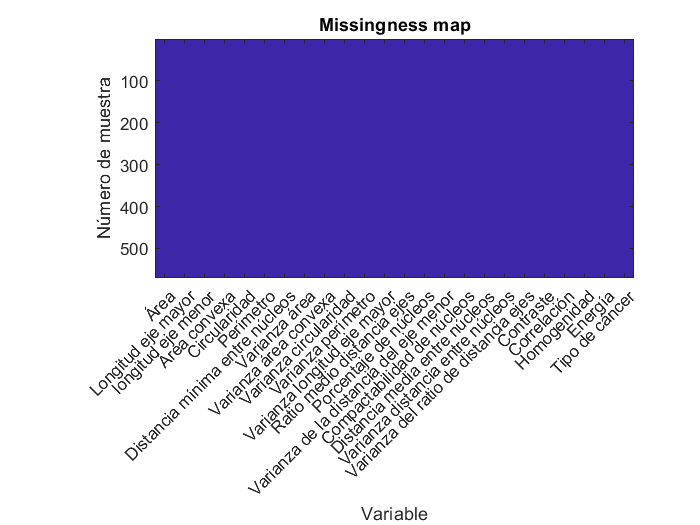

imagesc(ismissing(PreprocessedDdata,{'' '.' 'NA' NaN -99}))
xticks(1:length(Nombres));
xticklabels(Nombres);
xtickangle(45)
title('Missingness map');
xlabel('Variable');
ylabel('Número de muestra')

a=[1:7,13,14,16,17,20:23];
b=[24];
c=b;
units= ["um^2","um","um","um^2","-","um","um","-v","-v","-v","-v","-v","-","%(unitaria)","-v","-","um","-v","-v","-","-","-","-"];
[dataN,response_var,independent_vars,categorical_vars] =inconsistent_data(PreprocessedDdata,a,b,c);

for i=1:length(a)
    subplot(5,3,i)
    h = histfit(independent_vars(:,i));
    maximo(i) = max(h(2).XData);
    minimo(i) = min(h(2).XData);
    if minimo(i)<0
        minimo(i) = 0;
    end
    histfit(independent_vars(:,i))
    title(strcat('Histogram of the variable `',Nombres{a(i)},'´'));
    xlabel(units{a(i)});
end
l=1;

for p=1:height(dataN)
    if independent_vars(p,1:width(independent_vars))>minimo(1:width(independent_vars)) & independent_vars(p,1:width(independent_vars))<maximo(1:width(independent_vars))
        dataN1(l,:)=(dataN(p,:));
        l= l+1;
    end
end
independent_vars1 =  table2array(dataN1(:,a));
% independent_vars1 = table2array(independent_vars1);
for i=1:15
    fprintf('Mean value for variable %s is %.2f\n', Nombres{a(i)},mean(independent_vars1(:,i)));%FALTA TRADUCIR
    fprintf('Median for variable %s is %.2f\n', Nombres{a(i)},median(independent_vars1(:,i)));
    fprintf('Mode for variable %s is %.2f\n', Nombres{a(i)},mode(round(independent_vars1(:,i),1)));
    fprintf('Max. value for variable %s is %.2f\n', Nombres{a(i)},max(independent_vars1(:,i)));
    fprintf('Min. value for variable %s is %.2f\n', Nombres{a(i)},min(independent_vars1(:,i)));
    fprintf('Standard deviation for variable %s is %.2f\n \n', Nombres{a(i)},std(independent_vars1(:,i)));
end

Mean value for variable Área is 10.97


Median for variable Área is 11.03


Mode for variable Área is 10.00


Max. value for variable Área is 22.07


Min. value for variable Área is 4.33


Standard deviation for variable Área is 3.41
 


Mean value for variable Longitud eje mayor is 5.22


Median for variable Longitud eje mayor is 5.29


Mode for variable Longitud eje mayor is 5.40


Max. value for variable Longitud eje mayor is 7.05


Min. value for variable Longitud eje mayor is 3.52


Standard deviation for variable Longitud eje mayor is 0.69
 


Mean value for variable longitud eje menor is 2.69


Median for variable longitud eje menor is 2.69


Mode for variable longitud eje menor is 2.70


Max. value for variable longitud eje menor is 3.58


Min. value for variable longitud eje menor is 1.85


Standard deviation for variable longitud eje menor is 0.34
 


Mean value for variable Área convexa is 14.25


Median for variable Área convexa is 14.07


Mode for variable Área convexa is 12.80


Max. value for variable Área convexa is 32.44


Min. value for variable Área convexa is 5.18


Standard deviation for variable Área convexa is 4.71
 


Mean value for variable Circularidad is 0.62


Median for variable Circularidad is 0.61


Mode for variable Circularidad is 0.60


Max. value for variable Circularidad is 0.84


Min. value for variable Circularidad is 0.51


Standard deviation for variable Circularidad is 0.06
 


Mean value for variable Perímetro is 15.60


Median for variable Perímetro is 15.66


Mode for variable Perímetro is 14.60


Max. value for variable Perímetro is 24.60


Min. value for variable Perímetro is 8.78


Standard deviation for variable Perímetro is 2.81
 


Mean value for variable Distancia mínima entre núcleos is 0.00


Median for variable Distancia mínima entre núcleos is 0.00


Mode for variable Distancia mínima entre núcleos is 0.00


Max. value for variable Distancia mínima entre núcleos is 0.00


Min. value for variable Distancia mínima entre núcleos is 0.00


Standard deviation for variable Distancia mínima entre núcleos is 0.00
 


Mean value for variable Ratio medio distancia ejes is 2.11


Median for variable Ratio medio distancia ejes is 2.09


Mode for variable Ratio medio distancia ejes is 2.00


Max. value for variable Ratio medio distancia ejes is 2.68


Min. value for variable Ratio medio distancia ejes is 1.70


Standard deviation for variable Ratio medio distancia ejes is 0.17
 


Mean value for variable Porcentaje de núcleos is 0.89


Median for variable Porcentaje de núcleos is 0.88


Mode for variable Porcentaje de núcleos is 0.90


Max. value for variable Porcentaje de núcleos is 1.75


Min. value for variable Porcentaje de núcleos is 0.21


Standard deviation for variable Porcentaje de núcleos is 0.26
 


Mean value for variable Compactabilidad de núcleos is 0.39


Median for variable Compactabilidad de núcleos is 0.40


Mode for variable Compactabilidad de núcleos is 0.40


Max. value for variable Compactabilidad de núcleos is 0.74


Min. value for variable Compactabilidad de núcleos is 0.14


Standard deviation for variable Compactabilidad de núcleos is 0.11
 


Mean value for variable Distancia media entre núcleos is 0.23


Median for variable Distancia media entre núcleos is 0.22


Mode for variable Distancia media entre núcleos is 0.20


Max. value for variable Distancia media entre núcleos is 0.65


Min. value for variable Distancia media entre núcleos is 0.03


Standard deviation for variable Distancia media entre núcleos is 0.11
 


Mean value for variable Contraste is 0.37


Median for variable Contraste is 0.27


Mode for variable Contraste is 0.30


Max. value for variable Contraste is 1.07


Min. value for variable Contraste is 0.14


Standard deviation for variable Contraste is 0.23
 


Mean value for variable Correlación is 0.93


Median for variable Correlación is 0.94


Mode for variable Correlación is 0.90


Max. value for variable Correlación is 0.99


Min. value for variable Correlación is 0.80


Standard deviation for variable Correlación is 0.04
 


Mean value for variable Homogenidad is 0.86


Median for variable Homogenidad is 0.87


Mode for variable Homogenidad is 0.90


Max. value for variable Homogenidad is 0.94


Min. value for variable Homogenidad is 0.71


Standard deviation for variable Homogenidad is 0.05
 


Mean value for variable Energía is 0.11


Median for variable Energía is 0.11


Mode for variable Energía is 0.10


Max. value for variable Energía is 0.24


Min. value for variable Energía is 0.05


Standard deviation for variable Energía is 0.03
 


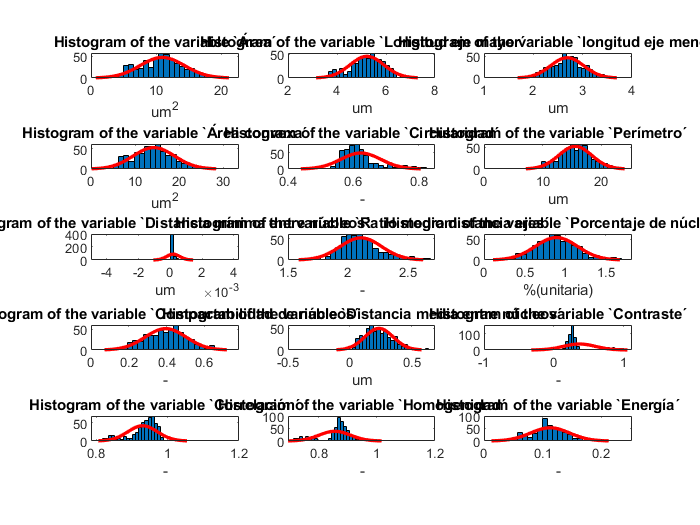

for i=1:length(a)
    subplot(5,3,i)
    h = histfit(independent_vars1(:,i));
    histfit(independent_vars1(:,i))
    title(strcat('Histogram of the variable `',Nombres{a(i)},'´'));
    xlabel(units{a(i)});
end

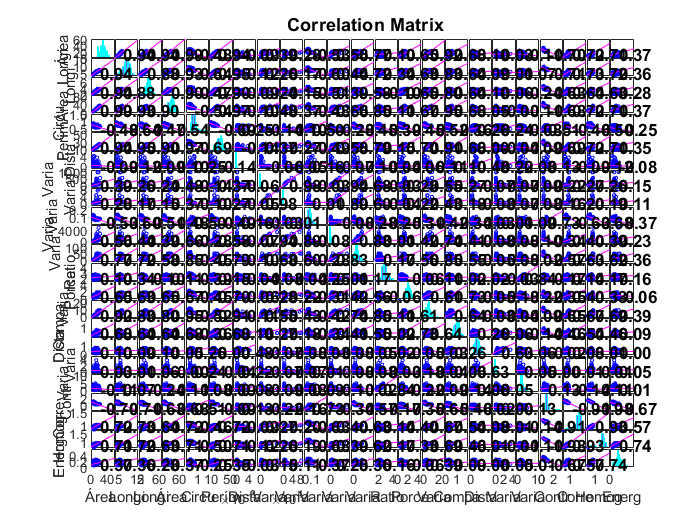

figure ()
corrplot(dataN1(:,1:23));

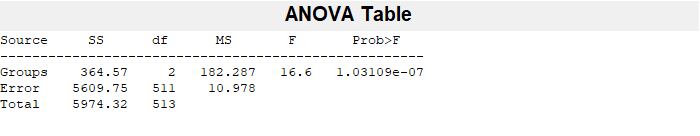

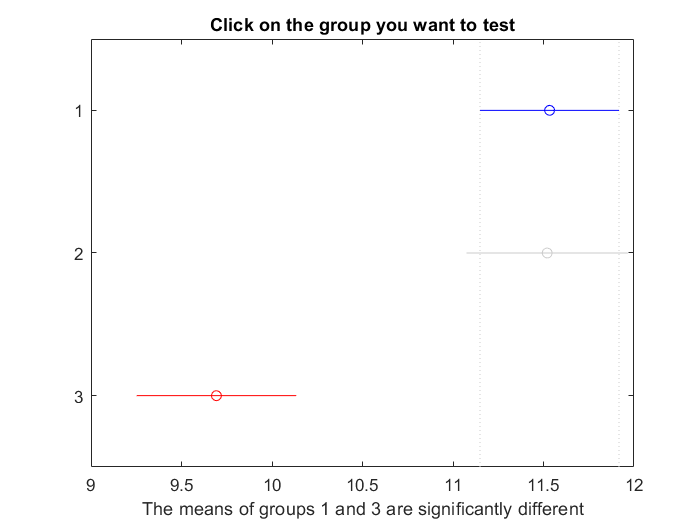

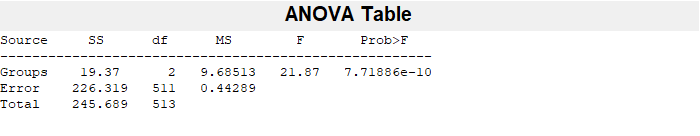

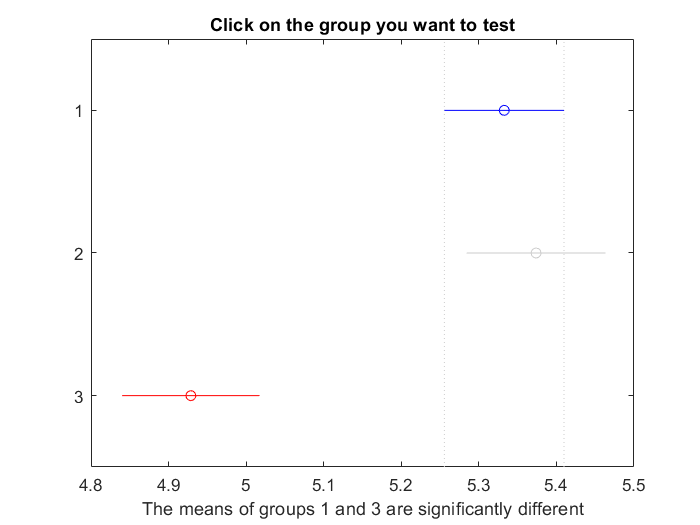

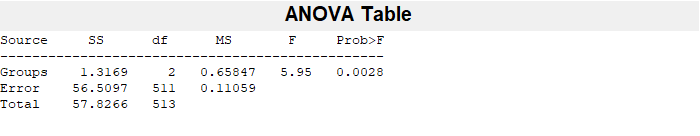

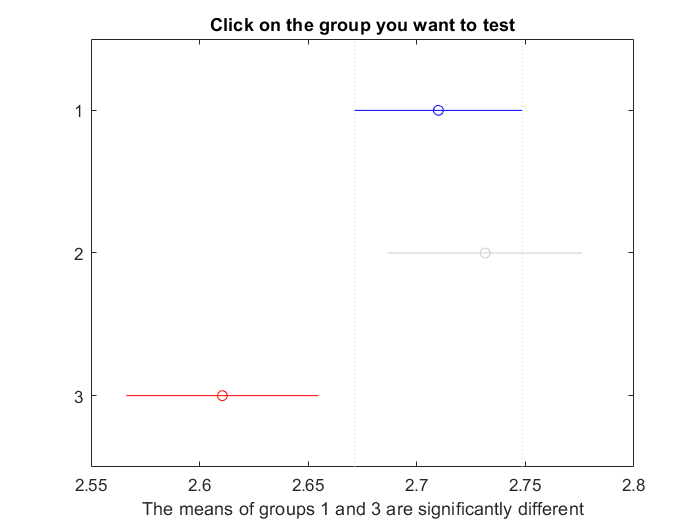

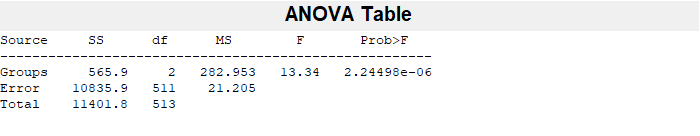

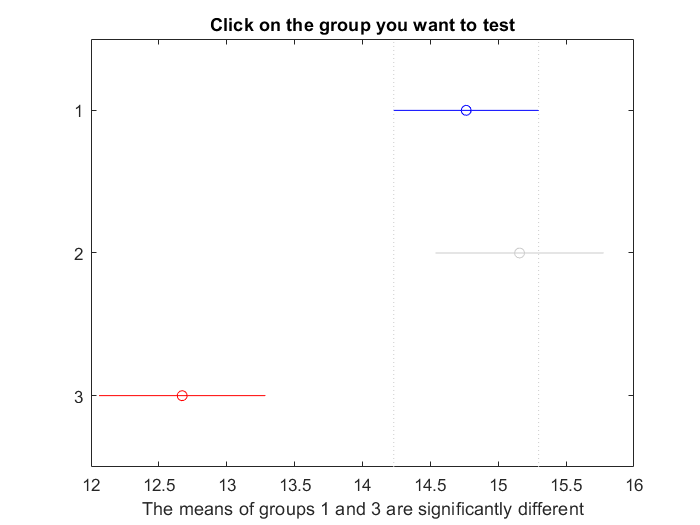


f=24;
[m1,n1]=size(dataN1);
categorical_vars1=table2array(dataN1(:,f));
dataN3=[];
dataN4=[];
dataN5=[];
for i = 1:m1

        if categorical_vars1 (i) == "N"
            dataN3 = [dataN3 i];
        end
        if categorical_vars1 (i) == "A"
            dataN4 = [dataN4 i];
        end
        if categorical_vars1 (i) == "M"
            dataN5 = [dataN5 i];
        end
end

taula_N = dataN1(transpose(dataN3),:);
taula_A = dataN1(transpose(dataN4),:);
taula_M = dataN1(transpose(dataN5),:);
DataAnova = [taula_N(:,1:23); taula_A(:,1:23); taula_M(:,1:23)];
DataAnova = rows2vars(DataAnova);
DataAnova(:,1)=[];
DataAnova = table2array(DataAnova);
% GroupsAnova = [rows2vars(taula_N(:,24)) rows2vars(taula_PB(:,24)) rows2vars(taula_UDH(:,24)) rows2vars(taula_FEA(:,24)) rows2vars(taula_ADH(:,24))  rows2vars(taula_DCIS(:,24)) rows2vars(taula_IC(:,24))];
optA=rows2vars(taula_N(:,24));
optB=rows2vars((taula_A(:,24)));
optC=rows2vars((taula_M(:,24)));
A1=ones(1,width(optA)-1);
B1=2.*ones(1,width(optB)-1);
C1=3.*ones(1,width(optC)-1);
GroupsAnova=[A1 B1 C1];
for a = 1:23
    [p1(a),ANOVATAB,stats] =anova1(DataAnova(a,:),GroupsAnova);
    p2(:,:,a) = multcompare(stats);
end


dataN2=(dataN1);
dataN22 = dataN2;
% for i=1:23
%     dataN2(:,i)=array2table(rescale(table2array(dataN1(:,i))));
% end
% dataN2=dataN1;
idx = fscmrmr(dataN2,"Tipo de cáncer")

idx =     18    16    10    19    21    23     7     5    17    13     4    22     2    12    14    20     8     1     9     6    11     3    15


% A=[3, 5, 7, 8, 11, 13, 17, 18, 19, 20, 22, 24]
% dataN2=dataN2(:,A);

## 1.KNN

k=8;
cvpt = cvpartition(dataN2.("Tipo de cáncer"),"Holdout",0.30);

dataTrain =dataN2(training(cvpt),:);
dataTest = dataN2(test(cvpt),:);
cvpt = cvpartition(dataTrain.("Tipo de cáncer"),"KFold",k)

cvpt = K-fold cross validation partition
   NumObservations: 360
       NumTestSets: 8
         TrainSize: 315  315  315  315  315  315  315  315
          TestSize: 45  45  45  45  45  45  45  45

mdlKNN = fitcknn(dataTrain, "Tipo de cáncer","NumNeighbors",3,"CVPartition",cvpt);
mdlLossKNN = kfoldLoss(mdlKNN) %This row will print the mean Loss value. 

mdlLossKNN = 0.5722

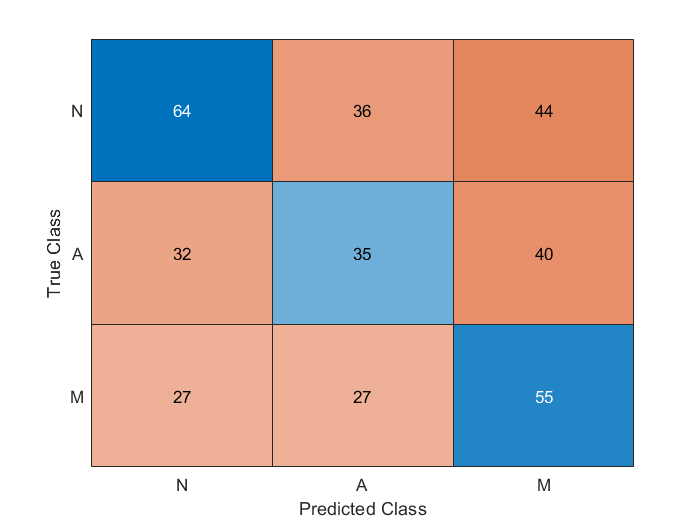

mdlLossKNN = kfoldLoss(mdlKNN, 'Mode', 'Individual'); %This row will compute the Loss for each Cross-Validation fold. This is interesting for the final comparisons. 
[yFit,sFit] = kfoldPredict(mdlKNN);
figure()
confusionchart(dataTrain.("Tipo de cáncer"),yFit)

## 2. DECISION TREE

mdlTree = fitctree(dataTrain, "Tipo de cáncer","CVPartition",cvpt);
mdlTreeLoss = kfoldLoss(mdlTree)

mdlTreeLoss = 0.4722

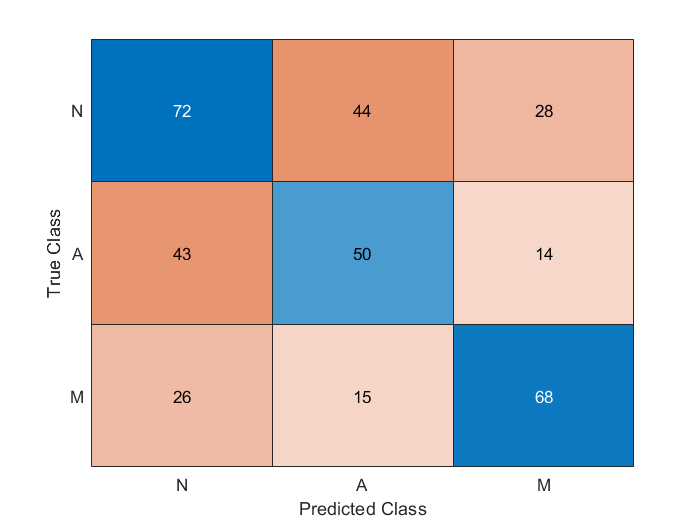

% mdlTreeLoss = 0.0927
mdlTreeLoss = kfoldLoss(mdlTree, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlTree);
confusionchart(dataTrain.("Tipo de cáncer"),yFit)

## 3. **Naive Bayes**

mdlNB = fitcnb(dataTrain, "Tipo de cáncer","CVPartition",cvpt);
mdlNBLoss = kfoldLoss(mdlNB)

mdlNBLoss = 0.4722

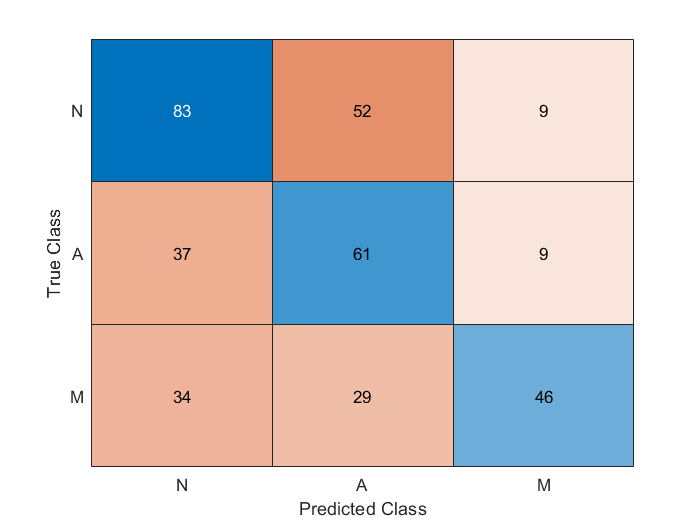

% mdlNBLoss = 0.0677
mdlNBLoss = kfoldLoss(mdlNB, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlNB);
confusionchart(dataTrain.("Tipo de cáncer"),yFit)

## **4.- LINEAR Discriminant Analysis**

mdlDisAn = fitcdiscr(dataTrain, "Tipo de cáncer","CVPartition",cvpt);
mdlDisAnLoss = kfoldLoss(mdlDisAn)

mdlDisAnLoss = 0.3250

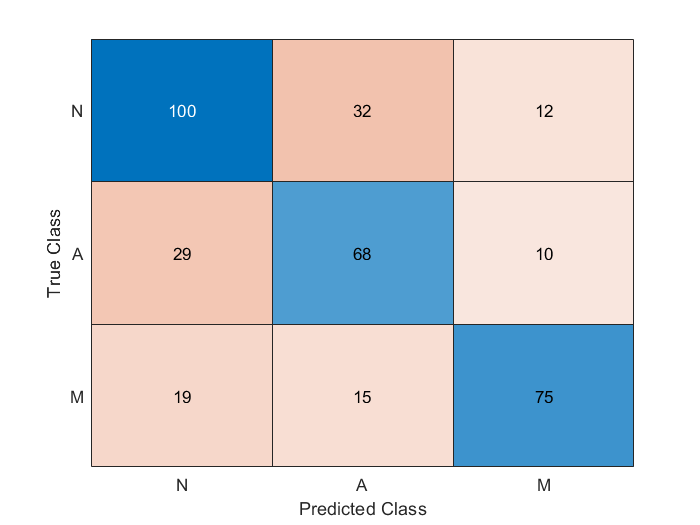


mdlDisAnLoss = kfoldLoss(mdlDisAn, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlDisAn);
confusionchart(dataTrain.("Tipo de cáncer"),yFit)

## 5-QUADRATIC Discriminant Analysis

mdlDisAnQ = fitcdiscr(dataTrain, "Tipo de cáncer","DiscrimType","quadratic","CVPartition",cvpt);
mdlDisAnQLoss = kfoldLoss(mdlDisAnQ)

mdlDisAnQLoss = 0.3583

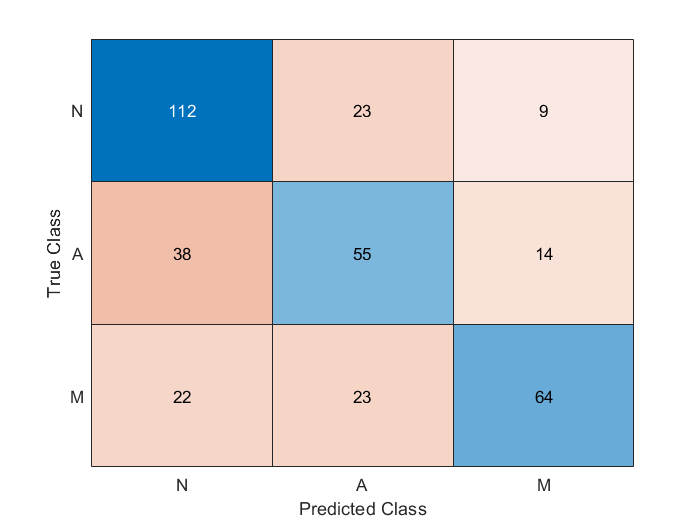

mdlDisAnQLoss = kfoldLoss(mdlDisAnQ, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlDisAnQ);
confusionchart(dataTrain.("Tipo de cáncer"),yFit)

## 6-SVM

mdlSvm = fitcecoc(dataTrain, "Tipo de cáncer","CVPartition",cvpt, "Coding","onevsone", "Learners","discriminant");
mdlSvmLoss = kfoldLoss(mdlSvm)

mdlSvmLoss = 0.3417

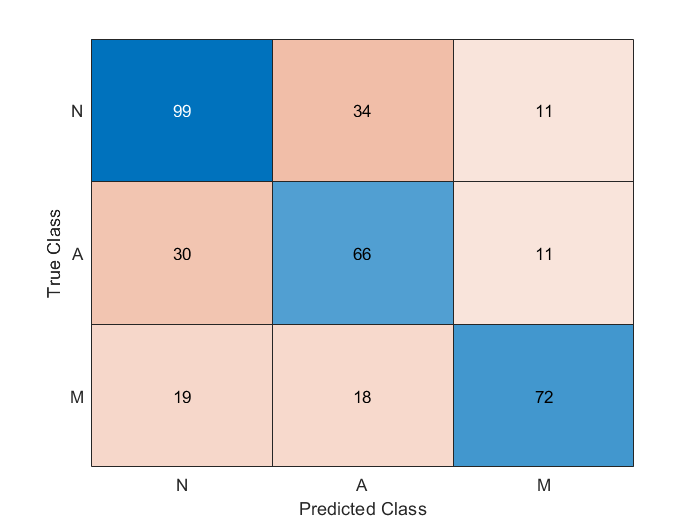


mdlSvmLoss = kfoldLoss(mdlSvm, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlSvm);
confusionchart(dataTrain.("Tipo de cáncer"),yFit)

## Línea de decisión

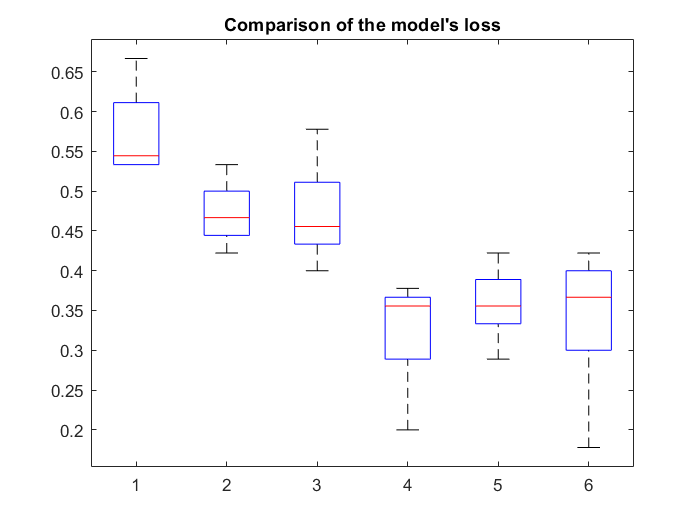

loss_matrix = [(mdlLossKNN),(mdlTreeLoss),(mdlNBLoss),(mdlDisAnLoss),(mdlDisAnQLoss),(mdlSvmLoss)];
boxplot(loss_matrix)
title("Comparison of the model's loss")

loss_matrix = [(mdlLossKNN),(mdlTreeLoss),(mdlNBLoss),(mdlDisAnLoss),(mdlDisAnQLoss),(mdlSvmLoss)];
boxplot(loss_matrix)
title("Comparison of the model's loss")


opts = delimitedTextImportOptions("NumVariables", 24);
% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";
% Specify column names and types
opts.VariableNames = ["Área", "Longitud eje mayor", "Longitud eje menor", "Área convexa","Circularidad", "Perímetro", "Distancia mínima entre núcleos", "Varianza área","Varianza área convexa","Varianza circularidad","Varianza perímetro","Varianza longitud eje mayor","Ratio medio distancia ejes","Porcentaje de núcleos","Varianza de la distancia del eje menor","Compactabilidad de núcleos","Distancia media entre núcleos","Varianza distancia entre núcleos","Varianza del ratio de distancia ejes","Contraste","Correlación", "Homogenidad","Energía","Tipo de cáncer"];
opts.VariableTypes = ["double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","categorical"];
% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
% Av = struct2cell(load("3_FEA.mat"));
% Av = Av{1,1};
% Bv = struct2cell(load("4_ADH.mat"));
% Bv = Bv{1,1};
load("tablavalBN.mat")
Taula = taula7;
% for i=1:23
%     dataN2(:,i)=array2table(rescale(table2array(dataN1(:,i))));
% end
% data_todo = dataN2;
for w=1:312
Taulav=Taula(w,:);
% for i=1:23
%     Taulav(:,i)=array2table(rescale(table2array(Taula(:,i))));
% end
load("validacion.mat")
TaulaV = processed(Taulav);
 %TaulaV(:, [1,2,3,4,5,9,12,13,15,16,17,18,22]) = [];

final_mdl = fitcecoc(dataN22, "Tipo de cáncer",'Coding','onevsone','Learners','discriminant');
Taulav=Taula;
%lrnrs = {templateKNN("NumNeighbors",4), templateDiscriminant, templateKNN("NumNeighbors", 2)}
%final_mdl = fitcensemble(data_todo, "Tipo de cáncer","Learners",lrnrs)

predictions = predict(final_mdl,TaulaV);
mdlLoss = loss(final_mdl,TaulaV)

if predictions=="N"
    load("data_corr.mat")
    final_mdlN = fitcecoc(data_corr, "Tipo de cáncer",'Coding','onevsone','Learners','discriminant');
    claseFinal(w) = predict(final_mdlN,TaulaV);
end
if predictions=="A"
    load("dataAN2.mat");
    dataAN2=dataN2;
    clear dataN2;
    Taulapn=Taula;
    for i=1:23
        Taulapn(:,i)=array2table(rescale(table2array(Taula(:,i))));
    end
    TaulaPN = processed(Taulapn);
    %TaulaPN(:, [1,2,3,4,5,9,12,13,15,16,17,18,22]) = [];
    final_mdlA = fitcecoc(dataAN2 , "Tipo de cáncer",'Coding','onevsone','Learners','discriminant');
    claseFinal(w) = predict(final_mdlA,TaulaV);
    JAJA = 2;
end
if predictions=="M"
    load("data_todo.mat");
    final_mdlM = fitcknn(data_todo, "Tipo de cáncer","NumNeighbors",2, 'DistanceWeight', 'inverse');
    claseFinal(w) = predict(final_mdlM,TaulaV);
    JAJA = 3;
end
end

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 1

mdlLoss = 1

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

mdlLoss = 0

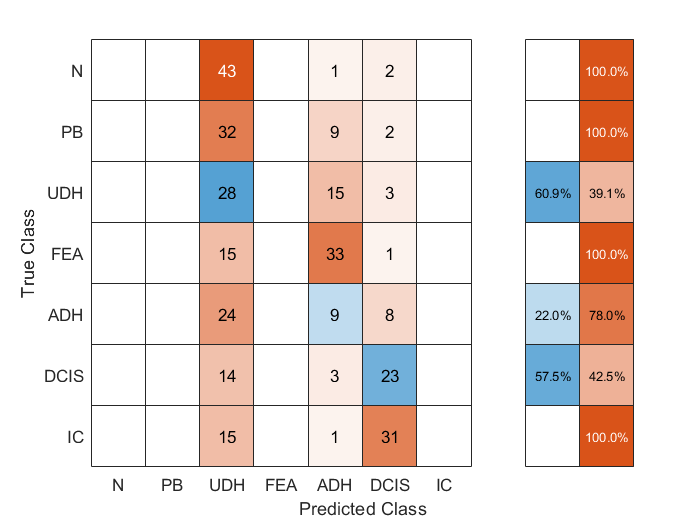

confusionchart(validacion.Var24,claseFinal,"RowSummary","row-normalized");

accuracy = sum(validacion.Var24==claseFinal)/numel(validacion.Var24)

accuracy =     0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1314    0.1282    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1282    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1474    0.1314    0.1282    0.1474
